y =     0.4314    0.8530
    0.9106    0.6221
    0.1818    0.3510
    0.2638    0.5132
    0.1455    0.4018
    0.1361    0.0760
    0.8693    0.2399
    0.5797    0.1233
    0.5499    0.1839
    0.1450    0.2400


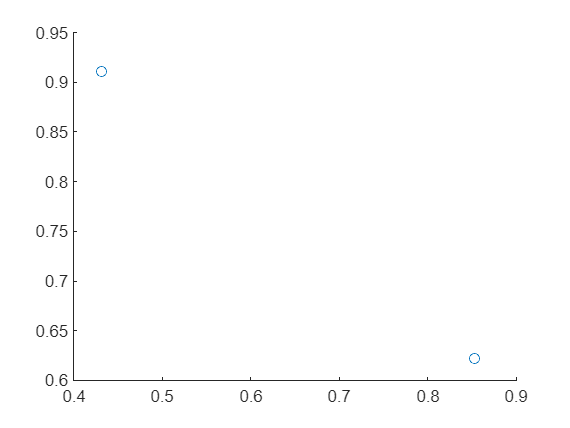

y =     0.1361    0.0760
    0.1450    0.1233
    0.1455    0.1839
    0.1818    0.2399
    0.2638    0.2400
    0.4314    0.3510
    0.5499    0.4018
    0.5797    0.5132
    0.8693    0.6221
    0.9106    0.8530


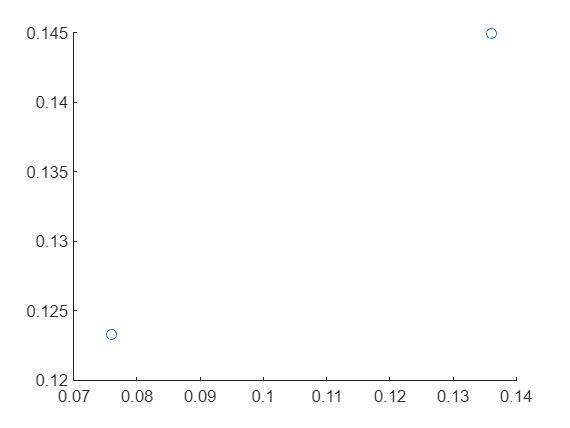

Index in position 2 exceeds array bounds. Index must not exceed 2.

Error in getLegendreCoefficientsND (line 24)
    phi(i) = f(y(:, i));

clc
clear

addpath("c:/git/UQ4PDE_Homeworks/Homework 4/functions/example functions/")
addpath("c:/git/UQ4PDE_Homeworks/Homework 4/functions/")
addpath("c:/git/UQ4PDE_Homeworks/Sparse Grids MATLAB/")



x = linspace(0, 1, 100);
w = 3;
N = 2;
M = 10;
type = 'TP';
f = @(x) f_gaussian(x);
getLegendreCoefficientsND(f, w, N, type, M)



%{
indxset = generateMultiIndexSet(N, w, 'HC');
scatter(indxset(:, 1), indxset(:, 2), 'filled')
xlim([0 w])
ylim([0 w])
grid()
% Tensor Product index set
figure()
indxset = generateMultiIndexSet(N, w, 'TD');
scatter(indxset(:, 1), indxset(:, 2), 'filled')
xlim([0 w])
ylim([0 w])
grid()
%}

%ex_function = @(x) f_gaussian(x);
%coeff = getLegendreCoefficients(ex_function, w);
%y = LegendreSeries(x, coeff);
%semilogy(1:2:w+1, abs(coeff(1:2:w+1)))